clear all; close all;

Correction of Example 2 using SYMBOLIC COMPUTING just to be close from the correction. OF COURSE DO NOT USE IN FEA, E A L will have values !!!

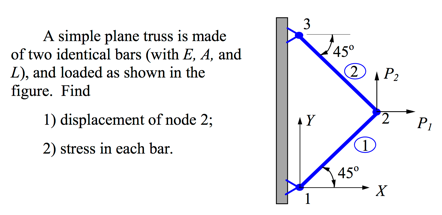

syms E A L real

alpha=E*A/L

$$alpha = \frac{A\,\text{E}}{L}$$

k=alpha*[1 -1;-1 1]

$$k = \left(\begin{array}{cc} \frac{A\,\text{E}}{L} & -\frac{A\,\text{E}}{L}\\ -\frac{A\,\text{E}}{L} & \frac{A\,\text{E}}{L} \end{array}\right)$$



%2 orientations 45;135°
%can also use symbolic here
%theta1 = sym([pi/43])
theta1=pi/4;
l1=cos(theta1);
m1=sin(theta1);
theta2=3*pi/4;
l2=cos(theta2);
m2=sin(theta2);

%augmented problem
T_tilde1=[l1 m1;-m1 l1];
T1=zeros(4,4);
T1(1:2,1:2)=T_tilde1;
T1(3:4,3:4)=T_tilde1

T1 =     0.7071    0.7071         0         0
   -0.7071    0.7071         0         0
         0         0    0.7071    0.7071
         0         0   -0.7071    0.7071



T_tilde2=[l2 m2;-m2 l2];
T2=zeros(4,4);
T2(1:2,1:2)=T_tilde2;
T2(3:4,3:4)=T_tilde2

T2 =    -0.7071    0.7071         0         0
   -0.7071   -0.7071         0         0
         0         0   -0.7071    0.7071
         0         0   -0.7071   -0.7071


%syms k_prime
k_prime=sym(zeros(4,4));
k_prime(1,1)=k(1,1);
k_prime(1,3)=k(1,2);
k_prime(3,1)=k(2,1);
k_prime(3,3)=k(2,2)

$$k\_prime = \left(\begin{array}{cccc} \frac{A\,\text{E}}{L} & 0 & -\frac{A\,\text{E}}{L} & 0\\ 0 & 0 & 0 & 0\\ -\frac{A\,\text{E}}{L} & 0 & \frac{A\,\text{E}}{L} & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


k1=T1'*k_prime*T1

$$k1 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & -\sigma_{1} & -\sigma_{1}\\ \sigma_{1} & \sigma_{1} & -\sigma_{1} & -\sigma_{1}\\ -\sigma_{1} & -\sigma_{1} & \sigma_{1} & \sigma_{1}\\ -\sigma_{1} & -\sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A\,\text{E}}{2\,L} \end{array}$$

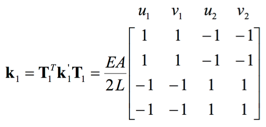

k2=T2'*k_prime*T2

$$k2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{1} & -\sigma_{1} & \sigma_{1}\\ -\sigma_{1} & \sigma_{1} & \sigma_{1} & -\sigma_{1}\\ -\sigma_{1} & \sigma_{1} & \sigma_{1} & -\sigma_{1}\\ \sigma_{1} & -\sigma_{1} & -\sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A\,\text{E}}{2\,L} \end{array}$$

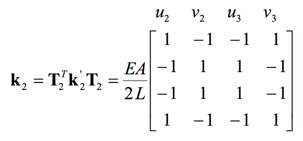


%assembly
K=sym(zeros(6,6));
K(1:4,1:4)=k1(1:4,1:4);
K(3:6,3:6)=k2(1:4,1:4);
K(3:4,3:4)= k1(3:4,3:4)+k2(1:2,1:2)

$$K = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{1} & \sigma_{1} & -\sigma_{1} & -\sigma_{1} & 0 & 0\\ \sigma_{1} & \sigma_{1} & -\sigma_{1} & -\sigma_{1} & 0 & 0\\ -\sigma_{1} & -\sigma_{1} & \frac{A\,\text{E}}{L} & 0 & -\sigma_{1} & \sigma_{1}\\ -\sigma_{1} & -\sigma_{1} & 0 & \frac{A\,\text{E}}{L} & \sigma_{1} & -\sigma_{1}\\ 0 & 0 & -\sigma_{1} & \sigma_{1} & \sigma_{1} & -\sigma_{1}\\ 0 & 0 & \sigma_{1} & -\sigma_{1} & -\sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A\,\text{E}}{2\,L} \end{array}$$


%DOF u2 v2


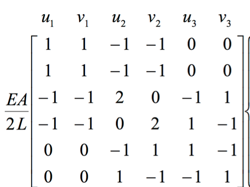


syms P1 P2 real

f=[0 0 P1 P2 0 0]'

$$f = \left(\begin{array}{c} 0\\ 0\\ P_{1}\\ P_{2}\\ 0\\ 0 \end{array}\right)$$

%full problem
U_full=inv(K)*f

$$U\_full = \left(\begin{array}{c} P_{1}\,\infty +P_{2}\,\infty \\ P_{1}\,\infty +P_{2}\,\infty \\ P_{1}\,\infty +P_{2}\,\infty \\ P_{1}\,\infty +P_{2}\,\infty \\ P_{1}\,\infty +P_{2}\,\infty \\ P_{1}\,\infty +P_{2}\,\infty \end{array}\right)$$

dof_condensed=[3:4];
%condensed
U_condensed=inv(K(dof_condensed,dof_condensed))*f(dof_condensed)

$$U\_condensed = \left(\begin{array}{c} \frac{L\,P_{1}}{A\,\text{E}}\\ \frac{L\,P_{2}}{A\,\text{E}} \end{array}\right)$$


%partionned
%   Special case: ALL imposed displacements are zero 
% (Ub = 0)

freedofs=[3:4];
constraineddofs=[1:2 5:6];
Kaa=K(freedofs,freedofs)

$$Kaa = \left(\begin{array}{cc} \frac{A\,\text{E}}{L} & 0\\ 0 & \frac{A\,\text{E}}{L} \end{array}\right)$$

Kba=K(constraineddofs,freedofs)

$$Kba = \left(\begin{array}{cc} -\frac{A\,\text{E}}{2\,L} & -\frac{A\,\text{E}}{2\,L}\\ -\frac{A\,\text{E}}{2\,L} & -\frac{A\,\text{E}}{2\,L}\\ -\frac{A\,\text{E}}{2\,L} & \frac{A\,\text{E}}{2\,L}\\ \frac{A\,\text{E}}{2\,L} & -\frac{A\,\text{E}}{2\,L} \end{array}\right)$$

fa=f(freedofs)

$$fa = \left(\begin{array}{c} P_{1}\\ P_{2} \end{array}\right)$$

Ua=inv(Kaa)*fa

$$Ua = \left(\begin{array}{c} \frac{L\,P_{1}}{A\,\text{E}}\\ \frac{L\,P_{2}}{A\,\text{E}} \end{array}\right)$$

R=Kba*Ua

$$R = \left(\begin{array}{c} -\frac{P_{1}}{2}-\frac{P_{2}}{2}\\ -\frac{P_{1}}{2}-\frac{P_{2}}{2}\\ \frac{P_{2}}{2}-\frac{P_{1}}{2}\\ \frac{P_{1}}{2}-\frac{P_{2}}{2} \end{array}\right)$$

%on x
R(1)+R(3)

$$ans = -P_{1}$$

%on y
R(2)+R(4)

$$ans = -P_{2}$$

%check u with longitudinal disp
%dim 1*2*2*4*4*1 
syms l m real
syms ui vi uj vj real
U=[ui vi uj vj]'

$$U = \left(\begin{array}{c} \mathrm{ui}\\ \mathrm{vi}\\ \mathrm{uj}\\ \mathrm{vj} \end{array}\right)$$

Tu=[l m 0 0; 0 0 l m]

$$Tu = \left(\begin{array}{cccc} l & m & 0 & 0\\ 0 & 0 & l & m \end{array}\right)$$

B=(1/L)*[-1 1]

$$B = \left(\begin{array}{cc} -\frac{1}{L} & \frac{1}{L} \end{array}\right)$$

S=E*B*Tu*U

$$S = \frac{\text{E}\,l\,\mathrm{uj}}{L}-\frac{\text{E}\,l\,\mathrm{ui}}{L}-\frac{\text{E}\,m\,\mathrm{vi}}{L}+\frac{\text{E}\,m\,\mathrm{vj}}{L}$$

% dim 1*2*2*4


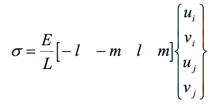

T1u=[T1(1,:);T1(3,:)];
Sigma1=E*B*T1u*[ Ua;0;0]

$$Sigma1 = -\frac{\sqrt{2}\,P_{1}}{2\,A}-\frac{\sqrt{2}\,P_{2}}{2\,A}$$

T2u=[T2(1,:);T2(3,:)];
Sigma2=E*B*T2u*[0;0; Ua]

$$Sigma2 = \frac{\sqrt{2}\,P_{2}}{2\,A}-\frac{\sqrt{2}\,P_{1}}{2\,A}$$